# Goal of the assignment: to do data pre-processing

in order to be able to feed the pre-processed data onto a NLP neural network that will Train a character-level language model to predict the next character in a sequence of text.

clc; clear all; close all;

## Import data

filename = "black_ship.txt"; % Name of the my chosen file
textData = extractFileText(filename); %File extract to get content of the data

## Tokenize data

documents = tokenizedDocument(textData);
disp(documents);

  tokenizedDocument:

   33481 tokens: The Project Gutenberg eBook of The black ship : with other allegories and parables This ebook is for the use of anyone anywhere in the United States and most other parts of the world at no cost and with almost no restrictions whatsoever . You may copy it , give it away or re-use it under the terms of the Project Gutenberg License included with this ebook or online at www.gutenberg.org . If you are not located in the United States , you will have to check the laws of the country where you are located before using this eBook . Title : The black ship : with other allegories and parables Author : Elizabeth Rundle Charles Release date : November 10 , 2024 [ eBook # 74714 ] Language : English Original publication : London : J . Nisbet & Co * * * START OF THE PROJECT GUTENBERG EBOOK THE BLACK SHIP : WITH OTHER ALLEGORIES AND PARABLES * * * Transcriber's notes : Unusual and incon

rawBag    = bagOfWords(documents)

rawBag =   bagOfWords with properties:

          Counts: [138 84 84 10 786 10 12 45 252 41 2 1240 4 22 2 189 180 1682 15 5 2 444 15 15 23 2 30 119 85 3 4 2 3 1228 26 31 12 330 2410 10 32 149 2 23 20 10 4 105 4 5 32 200 118 179 7 73 129 654 4 14 18 27 44 8 1 1 2 2 2 1 3 1 1 … ] (1×4626 double)
      Vocabulary: ["The"    "Project"    "Gutenberg"    "eBook"    "of"    "black"    "ship"    ":"    "with"    "other"    "allegories"    "and"    "parables"    "This"    "ebook"    "is"    "for"    "the"    "use"    "anyone"    …    ] (1×4626 string)
        NumWords: 4626
    NumDocuments: 1


After tokenizatio of the black ship text, there were `33481 tokens generated, however` there are 4626 individual vocabulary with the word "The" having the highest number of count as 138.

## Remove stop words

Note: modern NLP models do not need this step

documents = addPartOfSpeechDetails(documents); % This helps the removal of stop words.
documents = removeStopWords(documents);
documents = normalizeWords(documents,'Style','lemma');
documents = erasePunctuation(documents);
documents = removeShortWords(documents,2); % Remove words that are shorter than 2
documents = removeLongWords(documents,15); % Remove words that are longer than 15
afterBag  = bagOfWords(documents)

afterBag =   bagOfWords with properties:

          Counts: [88 88 14 38 43 5 10 5 2 16 16 14 31 5 4 2 3 24 23 32 2 22 18 14 4 7 8 21 19 1 2 2 2 2 1 4 1 1 1 3 1 4 1 2 2 6 1 3 3 1 1 5 10 4 7 2 4 3 1 2 1 3 54 50 11 2 1 3 1 2 3 2 6 19 20 37 4 50 30 14 1 75 10 22 13 2 7 28 5 9 6 … ] (1×3076 double)
      Vocabulary: ["project"    "gutenberg"    "ebook"    "black"    "ship"    "allegory"    "parable"    "anyone"    "anywhere"    "united"    "states"    "part"    "world"    "cost"    "almost"    "restriction"    "whatsoever"    …    ] (1×3076 string)
        NumWords: 3076
    NumDocuments: 1


After the removal of shorter and longer words, the number of vocavularies reduces to 3079 with the highest count as 112.

## Statistics on the preprocessing

Bags of words and n-grams

Wordcloud View of Cleaned data Againt Raw Data

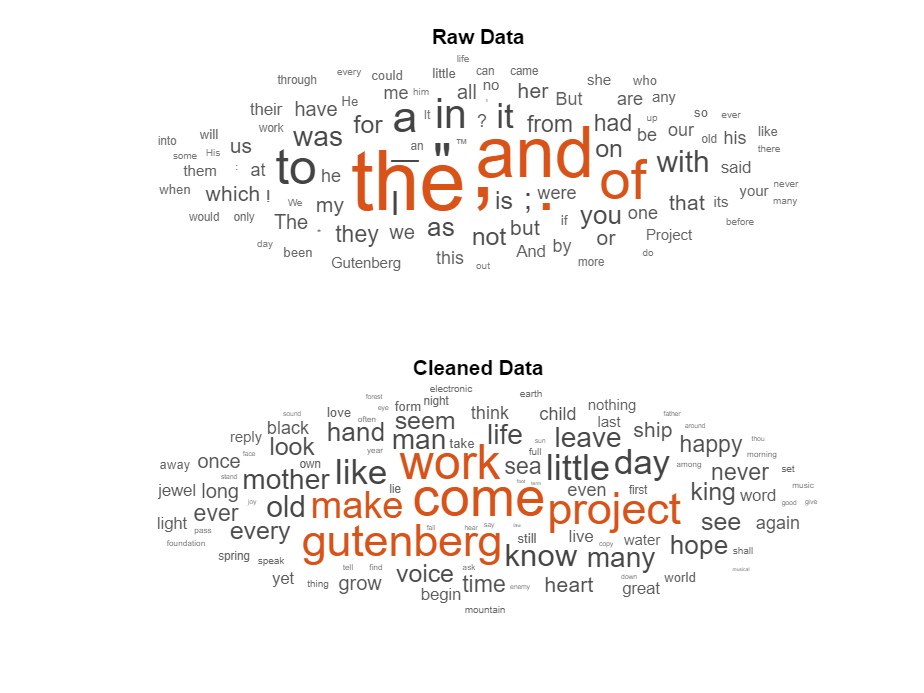

figure;
nexttile;
wordcloud(rawBag);
title("Raw Data");

nexttile;
wordcloud(afterBag);
title("Cleaned Data");

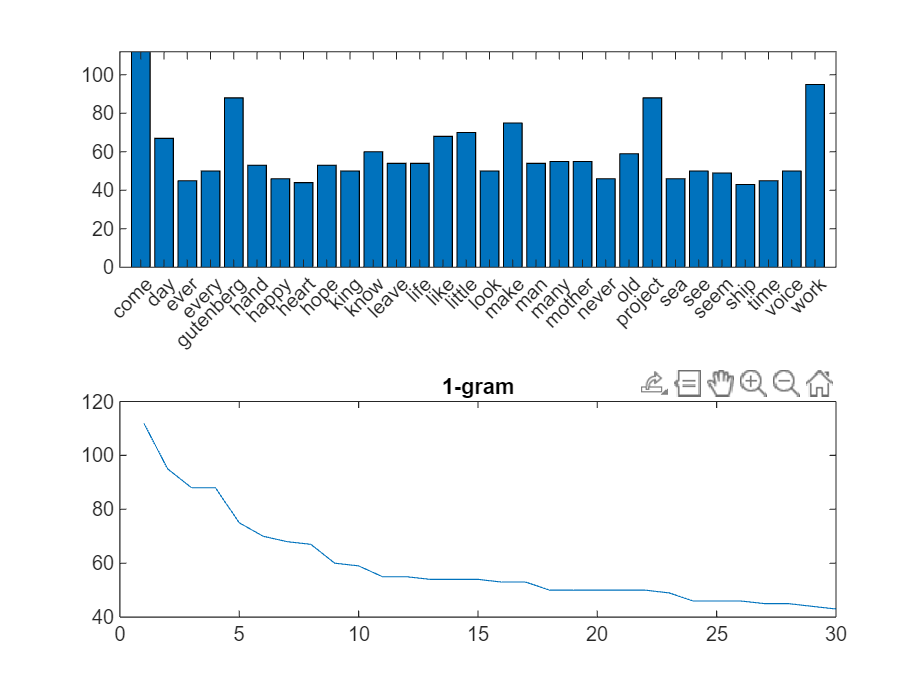

tblWords = topkwords(afterBag, 30);

figure; 
nexttile;
bar(categorical(tblWords.Word), tblWords.Count);

nexttile;
plot(tblWords.Count);
title("1-gram");

## N-gram analysis

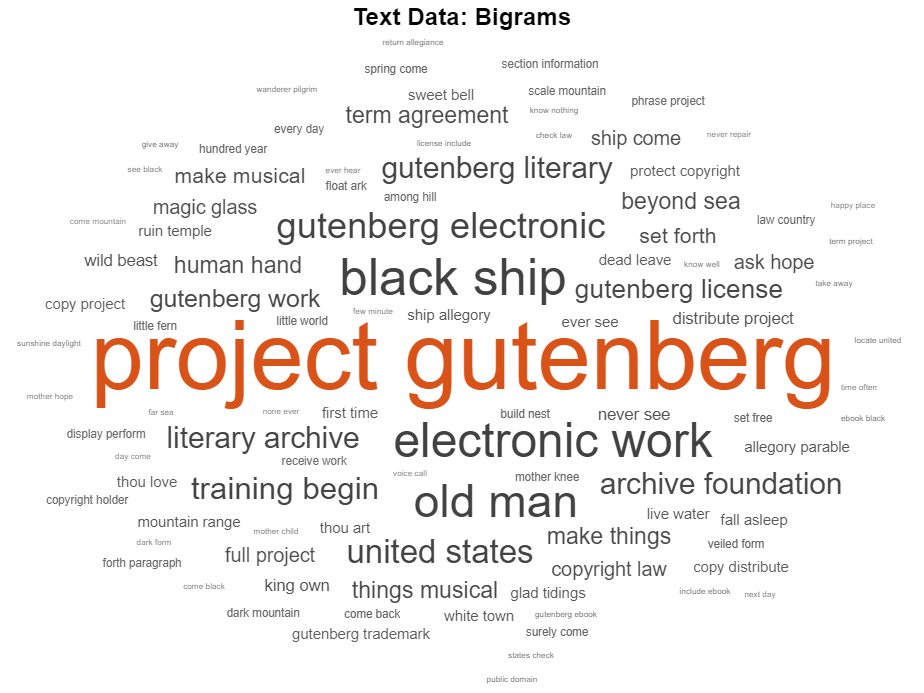

bag = bagOfNgrams(documents, NGramLengths=2);
figure
wordcloud(bag);
title("Text Data: Bigrams")

After 2gram.... it shown that "project gutenburg" are mostly  together since they have the same number of count and 2gram 

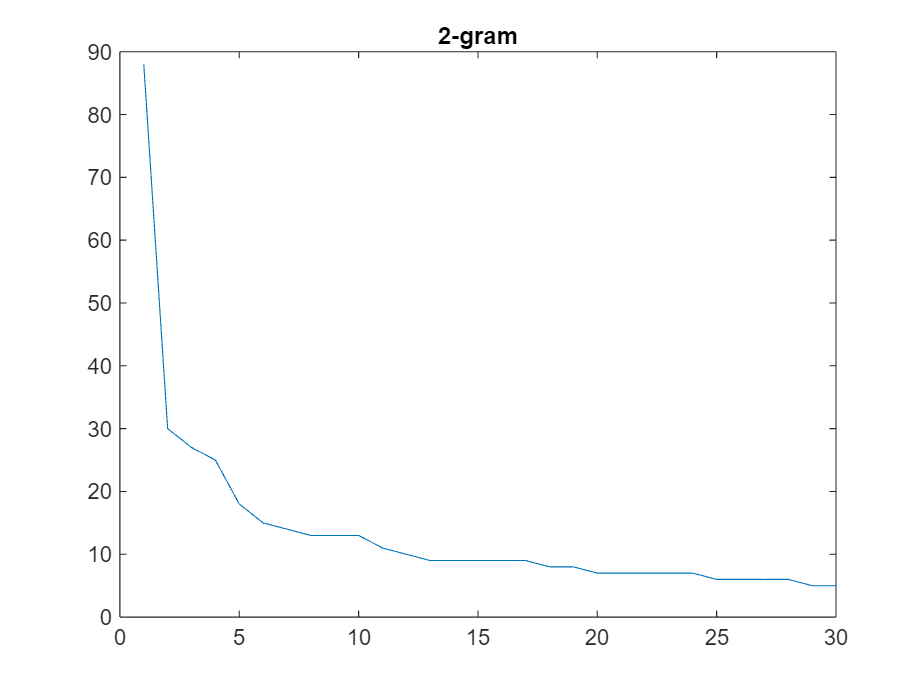


tblWords = topkngrams(bag, 30);

figure; 
plot(tblWords.Count);
title("2-gram");

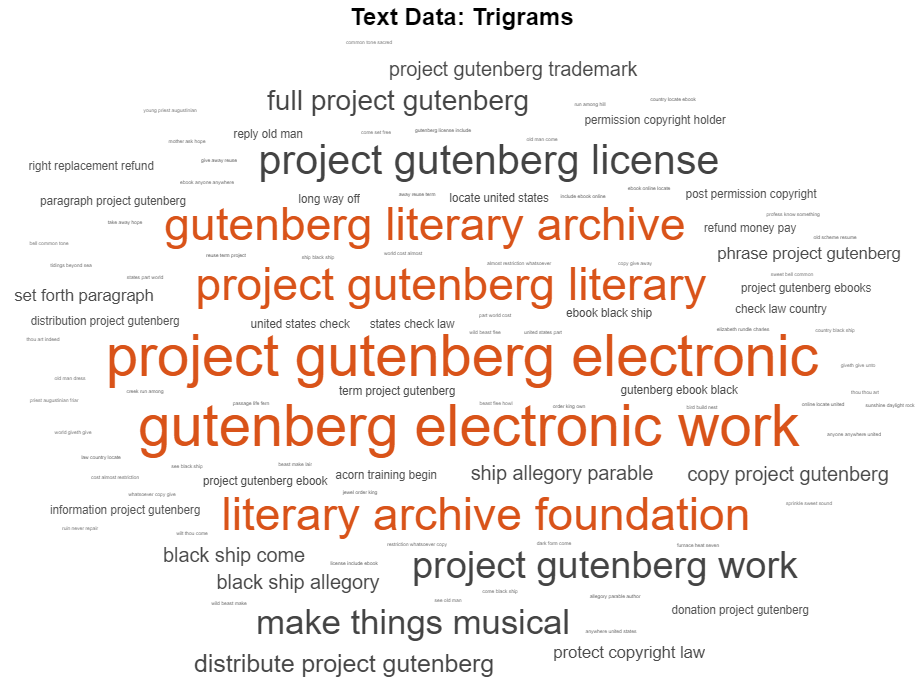

bag2 = bagOfNgrams(documents, NGramLengths=3);
figure
wordcloud(bag2);
title("Text Data: Trigrams")

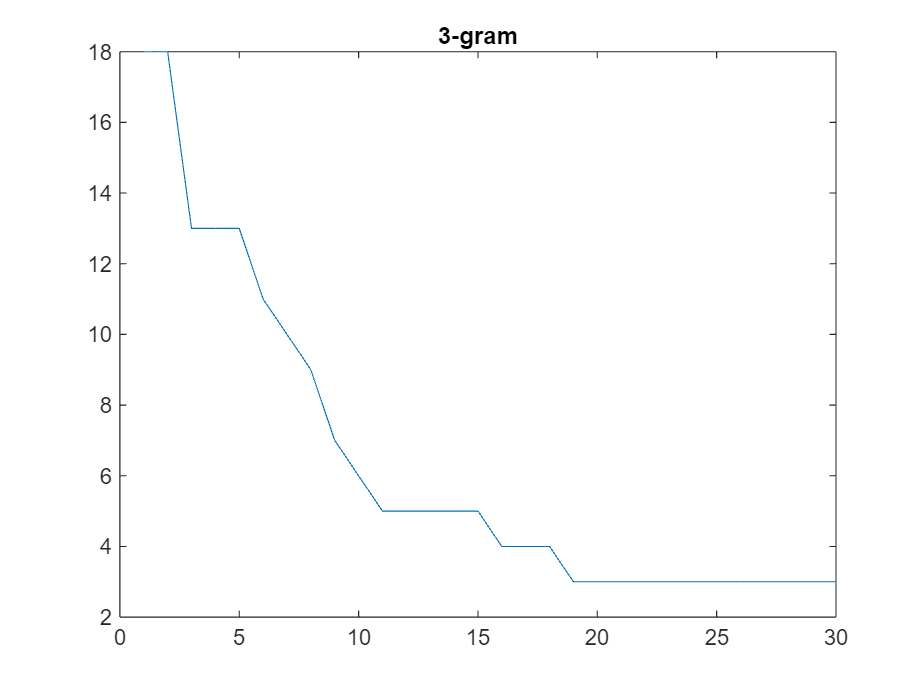

tblWords2 = topkngrams(bag2, 30);

figure; 
plot(tblWords2.Count);
title("3-gram");

## Converting documents into sequences

%textData = replace(textData, "  ", "");
%textData = replace(textData, " * * * ", "");
textData = split(textData, [newline]);  % Split the text into separate sonnets
textData = textData(111:end);           
textData

textData = 3092×1 string array
    "THEY lived at the foot of the Pine Mountains, in the island of the←"
    "King's Garden, the mother, with her little son and daughter. The boy's←"
    "name was Hope, and the little girl's, May.←"
    "←"
    "The children loved each other dearly, and were never separated. They←"
    "never had any quarrels, because Hope was the leader in all their←"
    "expeditions and plays; and May firmly believed that everything which←"
    "Hope planned and did, was better planned and better done than it would←"
    "have been by any one else in the world, by which May meant the island.←"
    "Hope, on his side, had always a tender consideration for little May in←"
    "his schemes, such as kings should have for their subjects. May would←"
    "never have dreamed of originating any scheme herself, or of questioning←"
    "any which Hope planned. If you had taken away May from Hope, you would←"
    "have taken away his kingdom, his army, his right hand; if you h

## Sequences of vectors for the predictors and categorical sequences for responses

Create special characters to denote "start of text", "whitespace", "end of text" and "newline". Use the special characters `"\x0002"` (start of text), `"\x00B7"` ("·", middle dot), `"\x2403"` ("␃", end of text), and `"\x00B6"` ("`¶`", pilcrow) respectively. To prevent ambiguity, you must choose special characters that do not appear in the text. Because these characters do not appear in the training data, they can be used for this purpose.

startOfTextCharacter    = compose("\x0002");
whitespaceCharacter     = compose("\x00B7");
endOfTextCharacter      = compose("\x2403");
newlineCharacter        = compose("\x00B6");


## Processing the data

so we can use them as inputs in a NN. 


textData            = startOfTextCharacter + textData;
textData            = replace(textData,[" " newline],[whitespaceCharacter newlineCharacter]);
uniqueCharacters    = unique([textData{:}]);
numUniqueCharacters = numel(uniqueCharacters);
numDocuments        = numel(textData);
XTrain              = cell(1,numDocuments);
YTrain              = cell(1,numDocuments);

for i = 1:numel(textData)
    characters = textData{i};
    sequenceLength = numel(characters);
    
    % Check if sequenceLength is greater than 2
    if sequenceLength > 2
        % Indices of characters
        [~, idx] = ismember(characters, uniqueCharacters);
        
        % Characters to vectors
        X = zeros(numUniqueCharacters, sequenceLength);
        for j = 1:sequenceLength
            X(idx(j), j) = 1;
        end
        
        % Vector of categorical responses with end-of-text character
        charactersShifted = [cellstr(characters(2:end)')' endOfTextCharacter];
        Y = categorical(charactersShifted);
        
        % Store in training sets
        XTrain{i} = X;
        YTrain{i} = Y;
    end
end

textData{1}

ans =     '□The·Project·Gutenberg·eBook·of·The·black·ship:·with·other·allegories·and·parables
     '


YTrain{1}

ans = 1×83 categorical array
     T      h      e      ·      P      r      o      j      e      c      t      ·      G      u      t      e      n      b      e      r      g      ·      e      B      o      o      k      ·      o      f      ·      T      h      e      ·      b      l      a      c      k      ·      s      h      i      p      :      ·      w      i      t      h      ·      o      t      h      e      r      ·      a      l      l      e      g      o      r      i      e      s      ·      a      n      d      ·      p      a      r      a      b      l      e      s      <undefined>      ␃ 


XTrain{1}

ans =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

Write an example pair of input (X) - output data (Y) pair for your case.

% Display the example input (X) and output (Y)
disp("Actual Text:");  

Actual Text:


disp(textData{1});

□THEY·lived·at·the·foot·of·the·Pine·Mountains,·in·the·island·of·the



disp("One-hot Encoded Input (X):");

One-hot Encoded Input (X):


disp(XTrain{1});  

     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  


disp("Display Output Sequence (Y):");

Display Output Sequence (Y):


disp(YTrain{1});  

     T      H      E      Y      ·      l      i      v      e      d      ·      a      t      ·      t      h      e      ·      f      o      o      t      ·      o      f      ·      t      h      e      ·      P      i      n      e      ·      M      o      u      n      t      a      i      n      s      ,      ·      i      n      ·      t      h      e      ·      i      s      l      a      n      d      ·      o      f      ·      t      h      e      <undefined>      ␃ 

